sound(y2);

%画出有噪声信号的Ryy
ny = 7000;
Ryy_y2 = conv(y2, flipud(y2))

Ryy_y2 = 1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


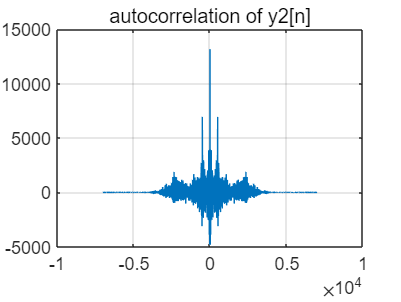

figure(1);
plot(-ny+1 : ny - 1, Ryy_y2);
grid on;
title('autocorrelation of y2[n]')

%通过算Ryy得到N = 500
N = 500;
Rxx = conv(z, flipud(z)); %原声信号为x，算出Rxx
mini_norm = 100000;
best_alpha = 0;

%遍历找best_alpha
for i = 1 : 9
    for j = 1 : 9
        alpha = 0.1 * i + j * 0.01;
        x_temp = filter(1, [1, zeros(1, N-1), alpha], y2); %还原的信号
        Rxx_temp = conv(x_temp, flipud(x_temp)).'; %算出还原信号的Rxx
%         %用Rxx算出还原信号的Ryy
%         Ryy_temp = (1 + alpha^2) * Rxx_temp + alpha * [zeros(1, N), Rxx_temp(1 : 2 * ny - 1 - N)] + alpha * [Rxx_temp(N+1 : 2*ny-1), zeros(1, N)];

        %和原声Rxx比较，如果降得很干净的话两个应该没啥差别
        error = Rxx - Rxx_temp.';
        disp(norm(error, 2));
        if norm(error, 2) < mini_norm
            mini_norm = norm(error, 2);
            disp(mini_norm);
            best_alpha = alpha;
        end
    end
end

   3.2719e+04



   3.2719e+04



   3.1946e+04



   3.1946e+04



   3.1189e+04



   3.1189e+04



   3.0448e+04



   3.0448e+04



   2.9723e+04



   2.9723e+04



   2.9013e+04



   2.9013e+04



   2.8318e+04



   2.8318e+04



   2.7637e+04



   2.7637e+04



   2.6971e+04



   2.6971e+04



   2.5681e+04



   2.5681e+04



   2.5056e+04



   2.5056e+04



   2.4444e+04



   2.4444e+04



   2.3846e+04



   2.3846e+04



   2.3260e+04



   2.3260e+04



   2.2688e+04



   2.2688e+04



   2.2127e+04



   2.2127e+04



   2.1579e+04



   2.1579e+04



   2.1044e+04



   2.1044e+04



   2.0010e+04



   2.0010e+04



   1.9510e+04



   1.9510e+04



   1.9023e+04



   1.9023e+04



   1.8548e+04



   1.8548e+04



   1.8085e+04



   1.8085e+04



   1.7634e+04



   1.7634e+04



   1.7196e+04



   1.7196e+04



   1.6769e+04



   1.6769e+04



   1.6355e+04



   1.6355e+04



   1.5564e+04



   1.5564e+04



   1.5188e+04



   1.5188e+04



   1.4825e+04



   1.4825e+04



   1.4475e+04



   1.4475e+04



   1.4140e+04



   1.4140e+04



   1.3818e+04



   1.3818e+04



   1.3512e+04



   1.3512e+04



   1.3221e+04



   1.3221e+04



   1.2945e+04



   1.2945e+04



   1.2445e+04



   1.2445e+04



   1.2221e+04



   1.2221e+04



   1.2016e+04



   1.2016e+04



   1.1832e+04



   1.1832e+04



   1.1668e+04



   1.1668e+04



   1.1526e+04



   1.1526e+04



   1.1407e+04



   1.1407e+04



   1.1313e+04



   1.1313e+04



   1.1245e+04



   1.1245e+04



   1.1192e+04



   1.1192e+04



   1.1210e+04

   1.1260e+04

   1.1344e+04

   1.1464e+04

   1.1621e+04

   1.1818e+04

   1.2057e+04

   1.2341e+04

   1.3052e+04

   1.3486e+04

   1.3976e+04

   1.4528e+04

   1.5145e+04

   1.5832e+04

   1.6596e+04

   1.7442e+04

   1.8378e+04

   2.0554e+04

   2.1813e+04

   2.3200e+04

   2.4730e+04

   2.6416e+04

   2.8274e+04

   3.0323e+04

   3.2583e+04

   3.5076e+04

   4.0866e+04

   4.4223e+04

   4.7934e+04

   5.2038e+04

   5.6579e+04

   6.1607e+04

   6.7178e+04

   7.3354e+04

   8.0205e+04



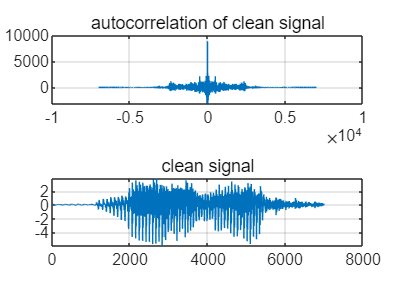

a_y2 = [1, zeros(1, N - 1), best_alpha];
x2 = filter(1, a_y2, y2); %还原y2为x2
sound(x2);
Rxx_x2 = conv(x2, flipud(x2));

figure(2);
subplot(2, 1, 1);
plot(-ny+1 : ny-1, Rxx_x2);
grid on;
title('autocorrelation of clean signal')

subplot(2, 1, 2);
plot(0 : ny-1, x2);
grid on;
title('clean signal')

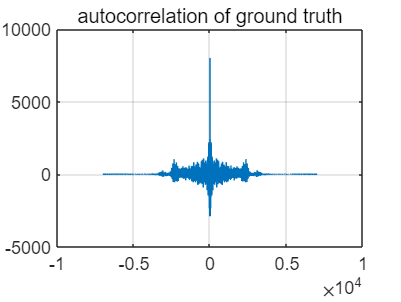


figure(3);
plot(-ny+1 : ny-1, Rxx);
grid on;
title('autocorrelation of ground truth')